## Load data from CSV file and clean data

clc
clear
close
data = readtable('csv/spd_1.500.csv');
% data_eddie = readtable('.\csv\450_0.750_physics.csv');
% Remove duplicate rows
clean_data = unique(data,'rows', 'stable');
noisy_data = clean_data(clean_data{:,4} > 0.0 & clean_data{:,4} < 2.5,:);
clean_data = clean_data(clean_data{:,4} >= 3.5 & clean_data{:, 4} <= 7.0, :);
writetable(clean_data, 'csv/spd_1.500_clean.csv');
% Extract time stamps and signal from data
time = clean_data{:, 6} + 1e-9.*clean_data{:,7};  % Assuming the first column contains time stamps
mean_front_signal = clean_data{:,1};  % Assuming the second column contains the signal data

## Processing the noisy data

mean_front = mean(noisy_data{:,1});
mean_rear = mean(noisy_data{:,2});
std_front = std(noisy_data{:,1});
std_rear = std(noisy_data{:,2});
% Model the noise using Gaussian distribution
noise_model_front = @(x) normpdf(x, mean_front, std_front);
noise_model_rear = @(x) normpdf(x, mean_rear, std_rear);

% filtered_data = mean_front_signal - noise_model_front(1:length(mean_front_signal))';
filtered_data = mean_front_signal;

## Compute time differences to estimate sampling intervals

time_diff = diff(time);
avg_sampling_interval = mean(time_diff); % Average sampling interval

% Perform FFT analysis
Fs = 1 / avg_sampling_interval;  % Estimated sampling frequency
L = length(filtered_data);  % Length of signal
f = Fs * (0:(L/2))/L;  % Frequency vector

Y = fft(filtered_data);  % Compute FFT
P2 = abs(Y/L);  % Compute two-sided spectrum
P1 = P2(1:L/2+1);  % Compute single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1);  % Double spectrum (excluding DC component)

% Find the maximum frequency
[max_amplitude, max_index] = max(P1);
max_frequency = f(max_index);
% max_frequency = 12;

% Define bandpass filter parameters
filter_range = 2;  % Range around max frequency to keep
filter_index = (f >= max_frequency - filter_range) & (f <= max_frequency + filter_range);
% filter_index = (f <= max_frequency + filter_range);

% Apply bandpass filter
filtered_signal = ifft(Y .* filter_index);


## Plot  FFT results

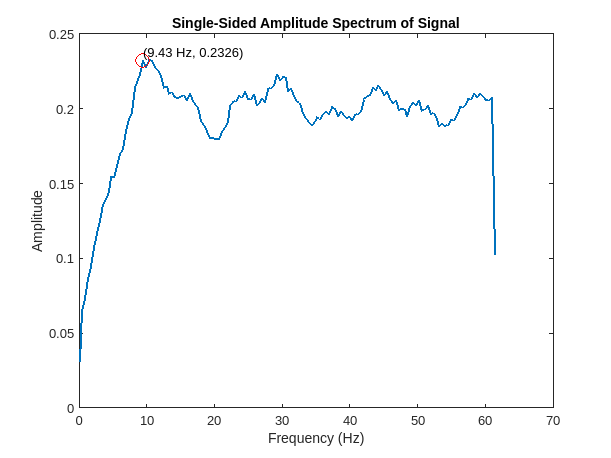

figure;
plot(f, P1, "LineWidth",1.5);
title('Single-Sided Amplitude Spectrum of Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

% Plot maximum frequency point
hold on;
plot(max_frequency, max_amplitude, 'ro', 'MarkerSize', 10);
text(max_frequency, max_amplitude, sprintf('(%.2f Hz, %.4f)', max_frequency, max_amplitude), 'VerticalAlignment', 'bottom');
hold off;

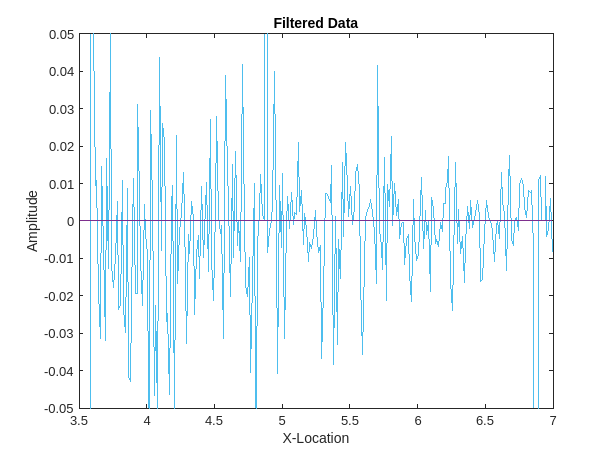


% Plot filtered data
figure;
plot(clean_data{:,4}, filtered_signal);
% xlim([4.0 18.2])
ylim([-0.05 0.05])
title('Filtered Data');
xlabel('X-Location');
ylabel('Amplitude');

% hold on



** Compare Results with Eddie**

% eddie_signal = readtable('eddie_csv/450_1.5_Accel_E.csv');
% eddie_filtered = readtable('eddie_csv/450_1.5_Accel_Filt_E.csv');


% Plot filtered data
% figure;
% hold on
% plot(time, filtered_signal,'c');
% plot(time(1,1)+eddie_filtered{:,1},abs(eddie_filtered{:,2}),'k')
% % plot(time(1,1)+eddie_signal{:,1},eddie_signal{:,2},'m')
% title('Filtered Data');
% xlabel('Time');
% ylabel('Amplitude');
% xlim([4.0 18.2])
% ylim([-2.5 2.5])










% time_diff = diff(time);
% avg_sampling_interval = mean(time_diff); % Average sampling interval

% % Perform FFT analysis
% Fs = 1 / avg_sampling_interval;  % Estimated sampling frequency
% L = length(filtered_signal(:,77));  % Length of signal
% f = Fs * (0:(L/2))/L;  % Frequency vector
% 
% Y = fft(filtered_signal(:,77));  % Compute FFT
% P2 = abs(Y/L);  % Compute two-sided spectrum
% P1 = P2(1:L/2+1);  % Compute single-sided spectrum
% P1(2:end-1) = 2*P1(2:end-1);  % Double spectrum (excluding DC component)
% 
% % Find the maximum frequency
% [max_amplitude, max_index] = max(P1);
% max_frequency = f(max_index);
% % max_frequency = 60;
% 
% figure;
% plot(f, P1, "LineWidth",1.5);
% title('Single-Sided Amplitude Spectrum of Signal');
% xlabel('Frequency (Hz)');
% ylabel('Amplitude');
% 
% % Plot maximum frequency point
% hold on;
% plot(max_frequency, max_amplitude, 'ro', 'MarkerSize', 10);
% text(max_frequency, max_amplitude, sprintf('(%.2f Hz, %.2f)', max_frequency, max_amplitude), 'VerticalAlignment', 'bottom');
% hold off;



% Define bandpass filter parameters
% filter_range = 1;  % Range around max frequency to keep
% filter_index = (f >= max_frequency - filter_range) & (f <= max_frequency + filter_range);
% 
% Apply bandpass filter
% filtered_signal = ifft(Y .* filter_index);
